%% Gradient Descent Setup Display & Comparison
% Displays: Function, Fixed α, Optimal α formula, Initial values
% Then runs comparison: Fixed α = 0.1 vs Exact Optimal αₖ = 0.25 (constant)
% f(x,y) = 3x² + y² | Starting point: (1, 3)
% Harsha S V – January 15, 2026

clear; clc; close all;

%% ==================== Problem Information Display ====================
fprintf('=====================================================================\n');

fprintf('                  GRADIENT DESCENT PROBLEM SETUP\n');

                  GRADIENT DESCENT PROBLEM SETUP


fprintf('=====================================================================\n');

fprintf('Function:          f(x,y) = 3x² + y²\n');

Function:          f(x,y) = 3x² + y²


fprintf('Initial values:    x₀ = 1,   y₀ = 3\n');

Initial values:    x₀ = 1,   y₀ = 3


fprintf('f(x₀,y₀) = 3(1)² + (3)² = 12\n\n');

f(x₀,y₀) = 3(1)² + (3)² = 12




fprintf('Fixed learning rate (manual entry):     α = 0.1\n\n');

Fixed learning rate (manual entry):     α = 0.1





fprintf('      α_k = (S^T S) / (S^T Q S)\n');

      α_k = (S^T S) / (S^T Q S)


fprintf('where S = ∇f(x_k) = [6x_k ; 2y_k]\n');

where S = ∇f(x_k) = [6x_k ; 2y_k]


fprintf('      Q = Hessian   = [6  0;\n');

      Q = Hessian   = [6  0;


fprintf('                       0  2]\n\n');

                       0  2]





fprintf('=====================================================================\n\n');


%% Surface Grid
x_grid = -4:0.1:4;
y_grid = x_grid;
[X, Y] = meshgrid(x_grid, y_grid);
Z = 3*X.^2 + Y.^2;

%% Parameters
epsilon = 1e-8;
max_iter = 300;
alpha_fixed = 0.1;

%% Storage
path_fixed = zeros(max_iter+1, 2);
path_opt   = zeros(max_iter+1, 2);
f_fixed    = zeros(max_iter+1, 1);
f_opt      = zeros(max_iter+1, 1);
alpha_opt_record = zeros(max_iter+1, 1);

% Initial point
path_fixed(1,:) = [1, 3];
path_opt(1,:)   = [1, 3];
f_fixed(1) = 12;
f_opt(1)   = 12;
alpha_opt_record(1) = NaN;

k = 1;

while k <= max_iter
    xk = path_opt(k, :);  % Use optimal path to maintain exact trajectory
    
    Sx = 6 * xk(1);
    Sy = 2 * xk(2);
    
    if norm([Sx, Sy]) < 1e-10
        break;
    end
    
    % Fixed α = 0.1
    x_next_fixed = path_fixed(k,:) - alpha_fixed * [Sx, Sy];
    path_fixed(k+1,:) = x_next_fixed;
    f_fixed(k+1) = 3*x_next_fixed(1)^2 + x_next_fixed(2)^2;
    
    % Optimal αₖ = exactly 0.25 (constant)
    alpha_opt_record(k+1) = 0.25;
    
    x_next_opt = xk - 0.25 * [Sx, Sy];
    path_opt(k+1,:) = x_next_opt;
    f_opt(k+1) = 3*x_next_opt(1)^2 + x_next_opt(2)^2;
    
    if abs(f_fixed(k+1) - f_fixed(k)) < epsilon && abs(f_opt(k+1) - f_opt(k)) < epsilon
        k = k + 1;
        break;
    end
    
    k = k + 1;
end

% Trim
n_points = k;
path_fixed = path_fixed(1:n_points,:);
path_opt   = path_opt(1:n_points,:);
f_fixed    = f_fixed(1:n_points);
f_opt      = f_opt(1:n_points);
alpha_opt_record = alpha_opt_record(1:n_points);

%% Comparison Table
fprintf('=== Iteration-wise Results ===\n');

=== Iteration-wise Results ===


fprintf('%-4s | %-22s | %-40s\n', 'Iter', 'Fixed α = 0.1', 'Exact Optimal αₖ = 0.25');

Iter | Fixed α = 0.1          | Exact Optimal αₖ = 0.25                 


fprintf('%-4s | %-8s %-8s %-10s | %-8s %-8s %-12s %-8s\n', ...
    '', 'x', 'y', 'f(x,y)', 'x', 'y', 'f(x,y)', 'αₖ');

     | x        y        f(x,y)     | x        y        f(x,y)       αₖ      


fprintf('%s\n', repmat('-', 1, 90));

------------------------------------------------------------------------------------------



for i = 1:n_points
    if i == 1
        fprintf('%-4d | %8.5f %8.5f %10.6f | %8.5f %8.5f %12.6f   %8s\n', ...
            i-1, path_fixed(i,1), path_fixed(i,2), f_fixed(i), ...
            path_opt(i,1), path_opt(i,2), f_opt(i), '(initial)');
    else
        fprintf('%-4d | %8.5f %8.5f %10.6f | %8.5f %8.5f %12.6f   %8.4f\n', ...
            i-1, path_fixed(i,1), path_fixed(i,2), f_fixed(i), ...
            path_opt(i,1), path_opt(i,2), f_opt(i), alpha_opt_record(i));
    end
end

0    |  1.00000  3.00000  12.000000 |  1.00000  3.00000    12.000000   (initial)


1    |  0.40000  2.40000   6.240000 | -0.50000  1.50000     3.000000     0.2500
2    |  0.70000  2.10000   5.880000 |  0.25000  0.75000     0.750000     0.2500
3    |  0.55000  1.95000   4.710000 | -0.12500  0.37500     0.187500     0.2500
4    |  0.62500  1.87500   4.687500 |  0.06250  0.18750     0.046875     0.2500
5    |  0.58750  1.83750   4.411875 | -0.03125  0.09375     0.011719     0.2500
6    |  0.60625  1.81875   4.410469 |  0.01562  0.04688     0.002930     0.2500
7    |  0.59688  1.80937   4.342617 | -0.00781  0.02344     0.000732     0.2500
8    |  0.60156  1.80469   4.342529 |  0.00391  0.01172     0.000183     0.2500
9    |  0.59922  1.80234   4.325632 | -0.00195  0.00586     0.000046     0.2500
10   |  0.60039  1.80117   4.325627 |  0.00098  0.00293     0.000011     0.2500
11   |  0.59980  1.80059   4.321407 | -0.00049  0.00146     0.000003     0.2500
12   |  0.60010  1.80029   4.321406 |  0.00024  0.00073     0.000001     0.2500
13   |  0.59995  1.80015   4.320352 | -0


fprintf('\nOptimal method converges very fast due to perfect constant αₖ = 0.25\n');


Optimal method converges very fast due to perfect constant αₖ = 0.25


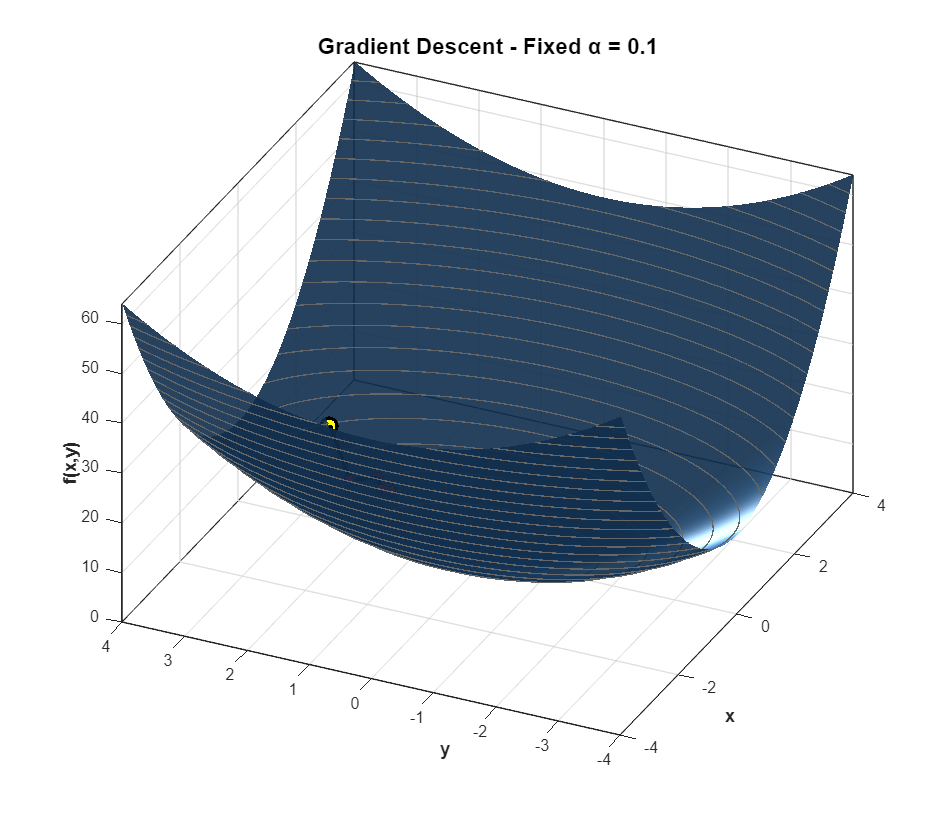


%% 3D Plots
figure('Color','white', 'Position',[100 100 800 700]);
surf(X, Y, Z, 'EdgeColor','none', 'FaceColor',[0.2 0.6 1], 'FaceAlpha',0.9);
hold on; contour3(X, Y, Z, 20, 'LineColor',[0.4 0.4 0.4], 'LineWidth',0.8);
plot3(path_fixed(:,1), path_fixed(:,2), f_fixed, 'k-', 'LineWidth', 2.5);
plot3(path_fixed(:,1), path_fixed(:,2), f_fixed, 'o', 'MarkerFaceColor','red', 'MarkerEdgeColor','black', 'MarkerSize',7);
plot3(1, 3, 12, 'o', 'MarkerFaceColor','yellow', 'MarkerEdgeColor','black', 'MarkerSize',10, 'LineWidth',2);
plot3(path_fixed(end,1), path_fixed(end,2), f_fixed(end), 'p', 'MarkerFaceColor','green', 'MarkerEdgeColor','black', 'MarkerSize',12);
colormap(parula); material shiny; lighting gouraud; light('Position',[10 10 10],'Style','local');
grid on; box on;
xlabel('x','FontWeight','bold'); ylabel('y','FontWeight','bold'); zlabel('f(x,y)','FontWeight','bold');
title('Gradient Descent - Fixed α = 0.1', 'FontSize',14,'FontWeight','bold');
view(-65,40); axis tight; hold off;

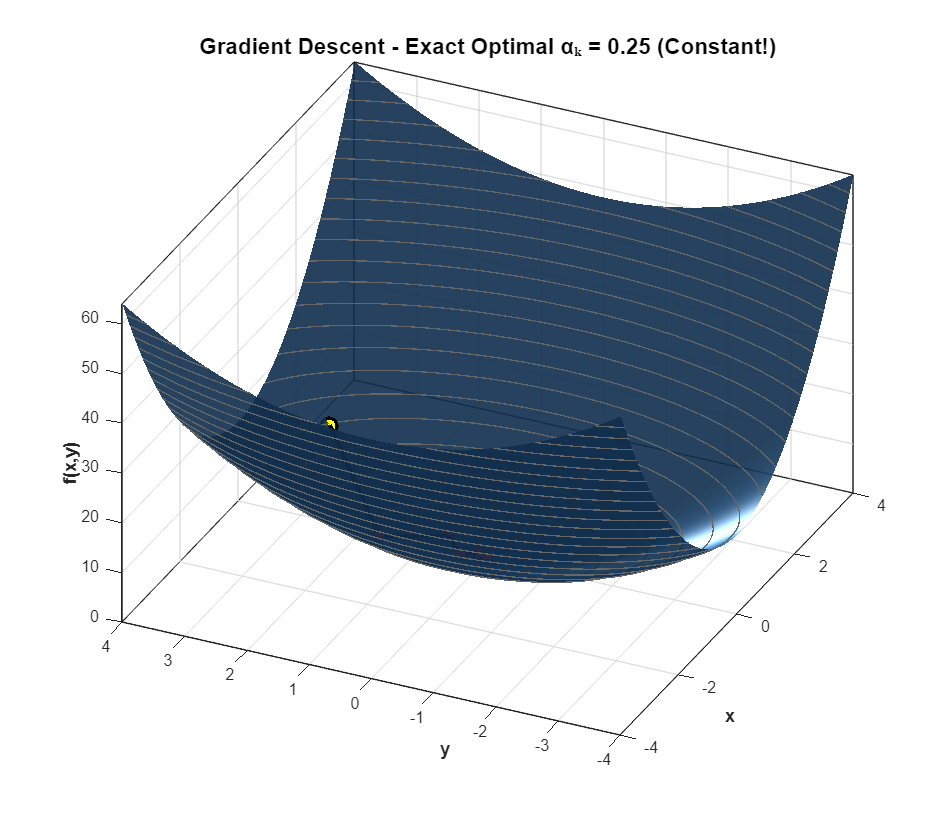


figure('Color','white', 'Position',[920 100 800 700]);
surf(X, Y, Z, 'EdgeColor','none', 'FaceColor',[0.2 0.6 1], 'FaceAlpha',0.9);
hold on; contour3(X, Y, Z, 20, 'LineColor',[0.4 0.4 0.4], 'LineWidth',0.8);
plot3(path_opt(:,1), path_opt(:,2), f_opt, 'k-', 'LineWidth', 2.5);
plot3(path_opt(:,1), path_opt(:,2), f_opt, 'o', 'MarkerFaceColor','red', 'MarkerEdgeColor','black', 'MarkerSize',7);
plot3(1, 3, 12, 'o', 'MarkerFaceColor','yellow', 'MarkerEdgeColor','black', 'MarkerSize',10, 'LineWidth',2);
plot3(path_opt(end,1), path_opt(end,2), f_opt(end), 'p', 'MarkerFaceColor','green', 'MarkerEdgeColor','black', 'MarkerSize',12);
colormap(parula); material shiny; lighting gouraud; light('Position',[10 10 10],'Style','local');
grid on; box on;
xlabel('x','FontWeight','bold'); ylabel('y','FontWeight','bold'); zlabel('f(x,y)','FontWeight','bold');
title('Gradient Descent - Exact Optimal αₖ = 0.25 (Constant!)', 'FontSize',14,'FontWeight','bold');
view(-65,40); axis tight; hold off;

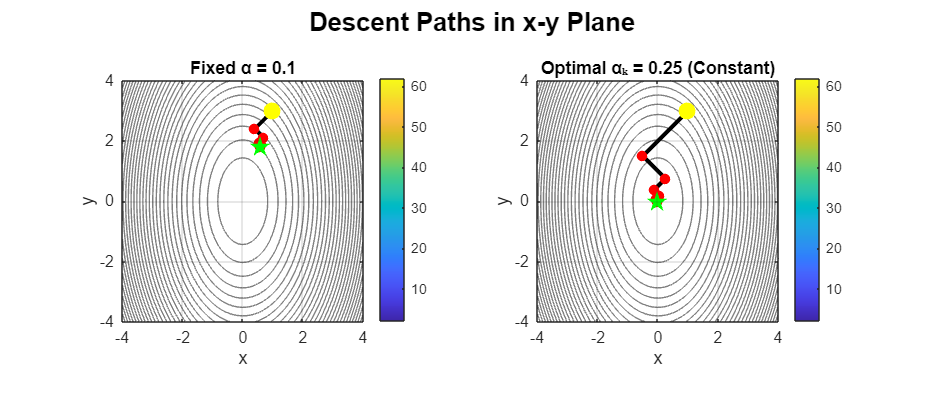


%% 2D Contour Side-by-Side
figure('Color','white', 'Position',[100 100 1300 550]);
subplot(1,2,1);
contour(X,Y,Z,30,'LineColor',[0.5 0.5 0.5]); hold on;
plot(path_fixed(:,1), path_fixed(:,2), 'k-', 'LineWidth',2.5);
plot(path_fixed(:,1), path_fixed(:,2), 'ro', 'MarkerFaceColor','red','MarkerSize',6);
plot(1,3,'yo','MarkerFaceColor','yellow','MarkerSize',10);
plot(path_fixed(end,1),path_fixed(end,2),'gp','MarkerFaceColor','green','MarkerSize',12);
title('Fixed α = 0.1'); xlabel('x'); ylabel('y'); grid on; axis equal tight; colorbar;

subplot(1,2,2);
contour(X,Y,Z,30,'LineColor',[0.5 0.5 0.5]); hold on;
plot(path_opt(:,1), path_opt(:,2), 'k-', 'LineWidth',2.5);
plot(path_opt(:,1), path_opt(:,2), 'ro', 'MarkerFaceColor','red','MarkerSize',6);
plot(1,3,'yo','MarkerFaceColor','yellow','MarkerSize',10);
plot(path_opt(end,1),path_opt(end,2),'gp','MarkerFaceColor','green','MarkerSize',12);
title('Optimal αₖ = 0.25 (Constant)'); xlabel('x'); ylabel('y'); grid on; axis equal tight; colorbar;

sgtitle('Descent Paths in x-y Plane', 'FontSize',16,'FontWeight','bold');